clc;
clear all;
close all;
addpath('C:\Users\Bryce Troncone\Desktop\Matlab Folder\SeaFreeze-master\SeaFreeze-master\Matlab')
%example below
% Identify phase for every 10 MPa from 0 to 1000 MPa and every 1 K from
% 200 to 355 K :
%out = SF_WhichPhase({0:1:10,200:1:355})
minP=0;
stepP=10;
maxP=2300;
minT=200;
maxT=400;
T1 = [minT:maxT]; %temperature range
P1 = [minP:maxP]; %pressure range
out = SF_WhichPhase({minP:stepP:maxP,minT:maxT});
imagesc(minT:maxT,minP:maxP,out);
ylabel('Pressure (MPa)')
xlabel('Temperature (K)')
hcb=colorbar

hcb =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [0 6]
    FontSize: 9
    Position: [0.8316 0.1095 0.0381 0.8159]
       Units: 'normalized'

  Show all properties


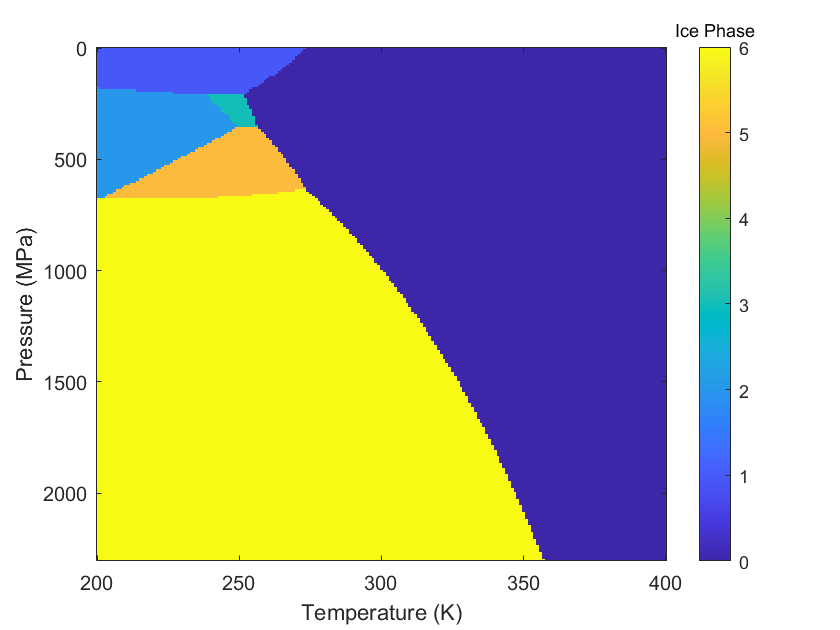


title(hcb,'Ice Phase')

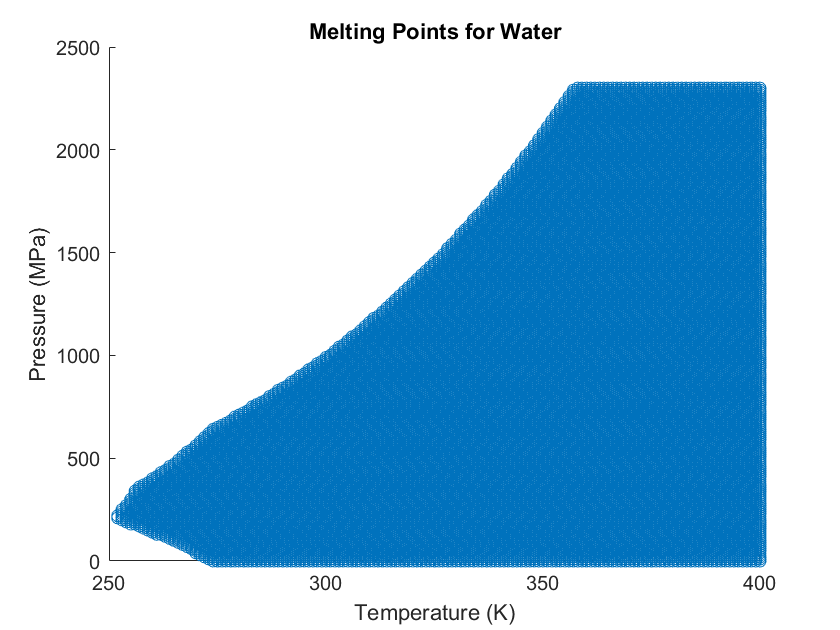

%e=out(22,53) %gets element's phase of a given index..ex. row22,column53=0
%[m,row]= min(out); % m=minimum value each column & first position (row) of occurence
%[m,col]= min(min(out));

nT1=repmat(T1,231,1);

mT=nT1(find(out==0));

P1_short=minP:stepP:maxP;

nP1=reshape(repmat(P1_short',201,1)', 231,201);

mP=nP1(find(out==0));

scatter(mT,mP)
ylabel('Pressure (MPa)')
xlabel('Temperature (K)')
title('Melting Points for Water')

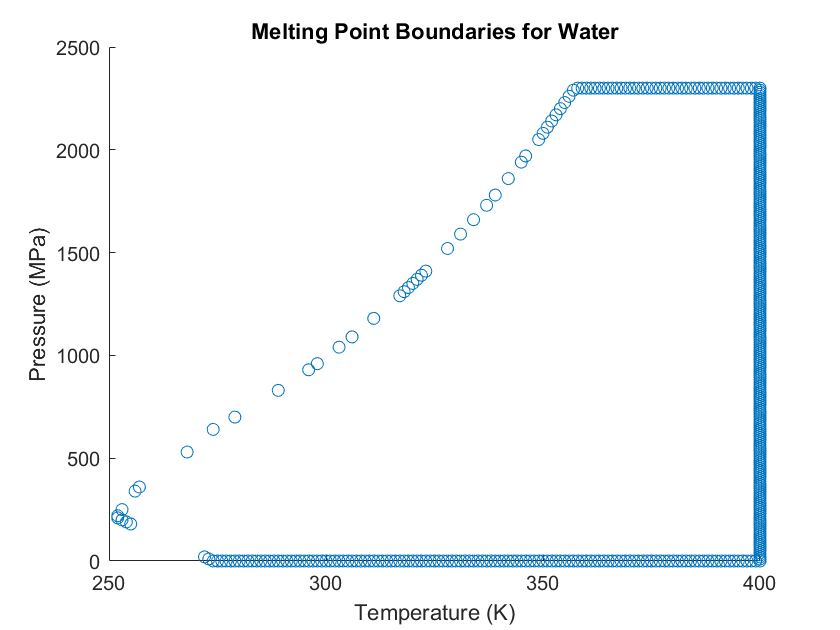

k=boundary(mT,mP);
scatter(mT(k), mP(k))
ylabel('Pressure (MPa)')
xlabel('Temperature (K)')
title('Melting Point Boundaries for Water')


% 0 = liquid
% 1 = ice Ih
% 2 = ice II
% 3 = ice III
% 5 = ice V
% 6 = ice VI